# P3. ACC Controller Design

Vehicle Control Systems

Degree in Electronics, Robotics and Mechatronics Engineering

University of Malaga

Created by: David Rodríguez Martínez

Last updated: 14 October 2026

### Introduction and objectives

This file contains both the coursework instructions and the code blocks to complete. This exercise reuses the previously defined race-car model and extends the P1 longitudinal controller to adaptive cruise control (ACC).

P1 defined a simple longitudinal controller controlLongitudinal(v_ref, vx, e_int,..). Here we give the controller its final interface for simulating the FS Driverless competition.

% [Fx, mem] = controlLongitudinal(est, ref, p, mem)

- `est = estimated vehicle state (position, speed, etc.)`

- `ref = desired references: cruise speed (ref.v_set) and lead-vehicle information (ref.lead_X, ref.lead_vx)`

- p = parameters (mass, resistance, limits, gains, dt, etc.)

- mem = controller memory: internal state retained between steps, including integrators and previous commands.

Memory: most ECUs execute in discrete time, with limiters, integrators and filters retaining previous states between execution cycles.

After completing this exercise, you should be able to:

- Understand the difference between conventional cruise control and ACC.

- Implement a constant-time-headway (CTH) ACC law that can switch between speed and gap modes.

- Close the longitudinal control loop.

#### What you will implement

A) The ACC law as part of controlLongitudinal.

### Vehicle, controller and road parameters

p = struct(); 

p.m    = 230;      % mass [kg]
p.g    = 9.81;     % gravity [m/s^2]
p.rho  = 1.225;    % air density [kg/m^3]
p.Cd   = 1.0;      % aerodynamic coefficient
p.Af   = 1.1;      % frontal area [m^2]
p.fr  = 0.022;    % rolling-resistance coefficient
p.Fx_drive_max = 2500;   % maximum driving force [N]
p.Fx_brake_max = 5000;   % maximum braking force [N]
p.theta        = 0;      % road inclination [rad]

% adhesion per axle
p.mu_t = 1.5; 
p.mu_d = 0.95*p.mu_t; 

% vehicle lateral dynamics
p.ld = 0.765; % CG to front axle [m]
p.lt = 0.765; % CG to rear axle [m]
p.Iz = 130; % yaw inertia [kg*m^2]
p.Cad = 35000; % front cornering stiffness [N/rad]
p.Cat = 50000; % rear cornering stiffness [N/rad]

% ACC law
p.d0 = 6; % minimum stopping gap [m]
p.h = 1.5; % time-headway threshold [s]
p.Kv = 1.5; % speed-mode gain
p.Kg = 0.4; % gap-mode gain
p.Kd = 1,0; % derivative gain on relative speed

p = struct with fields:
               m: 230
               g: 9.8100
             rho: 1.2250
              Cd: 1
              Af: 1.1000
              fr: 0.0220
    Fx_drive_max: 2500
    Fx_brake_max: 5000
           theta: 0
            mu_t: 1.5000
            mu_d: 1.4250
              ld: 0.7650
              lt: 0.7650
              Iz: 130
             Cad: 35000
             Cat: 50000
              d0: 6
               h: 1.5000
              Kv: 1.5000
              Kg: 0.4000
              Kd: 1


p.jerk_max = 30; % acceleration-rate limit (jerk; reduce jolts and improve comfort)

% simulation-specific parameters
p.v_set = 25; % desired cruise speed [m/s]
p.dt = 0.002; % simulation time step
esc.lead_X0 = 30; % initial lead-vehicle position
esc.Tmax = 22; % maximum simulation time


### Vehicle model

Given the current vehicle state, applied driving force and steering angle, calculate where the vehicle will be at the next time step.

function z_next = pasoDinamico(z, u, p, dt)
    Fx = u(1);
    delta = u(2);
    X = z(1); Y =z(2); psi = z(3);
    vx = z(4); vy = z(5); r = z(6);
    L = p.ld + p.lt;
    vx_c = max(vx, 1.0); % corrected speed to avoid division by zero in slip angles
    
    % slip angles and lateral forces
    alpha_d = delta - (vy + p.ld*r)/vx_c;
    alpha_t = - (vy - p.lt*r)/vx_c;
    Fyd = p.Cad*alpha_d; % linear tyre model
    Fyt = p.Cat*alpha_t; % linear tyre model

    % Adhesion limit (mu*Fz budget per axle)
    Fzd = p.m*p.g*p.lt/L;  
    Fzt = p.m*p.g*p.ld/L;

ACC — separación mínima: 19.3 m  (líder frena en t=14 s)


    % Front-axle saturation
    Fyd = max(min(Fyd, p.mu_d*Fzd), -p.mu_d*Fzd); 
    % Rear-axle saturation
    Fyt = max(min(Fyt, p.mu_t*Fzt), -p.mu_t*Fzt);
    % Longitudinal grip

  sin colisión: separación siempre > 0


    Fx_max = p.mu_d*Fzd + p.mu_t*Fzt;
    Fx = max(min(Fx, Fx_max), - Fx_max);

  velocidad final ego: 30.3 km/h | líder: 28.8 km/h


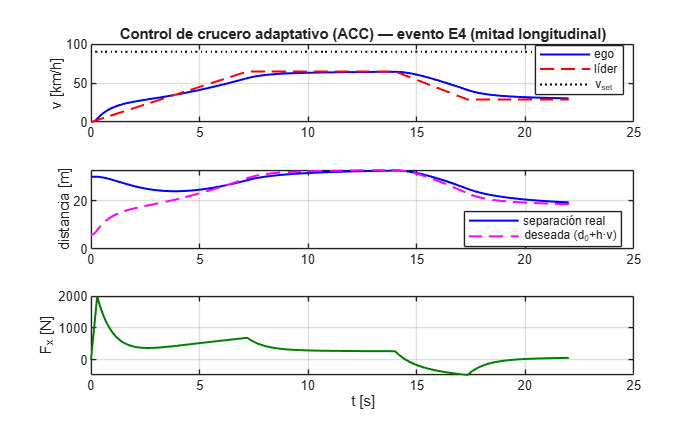


    % Longitudinal dynamics
    Ra = 0.5*p.rho*p.Cd*p.Af*vx^2;      % aerodynamic resistance
    Rr  = p.fr*p.m*p.g*cos(p.theta);    % rolling resistance opposing travel
    Rg = p.m*p.g*sin(p.theta);          % gravity

    % Equations of motion (chassis CG)
    ax_l    = (Fx - Ra - sign(vx)*Rr- Rg) / p.m; % longitudinal equation of motion (P1)
    ax = ax_l + vy*r; % P1 plus centripetal coupling from turning the velocity vector
    ay = (Fyd + Fyt)/p.m - vx*r; 
    dr  = (p.ld*Fyd - p.lt*Fyt)/p.Iz;


    % Integration and global kinematics
    vx_next  = max(vx + ax*dt, 0);
    vy_next  = vy + ay*dt;
    r_next   = r  + dr*dt;
    X_next   = X + (vx*cos(psi) - vy*sin(psi))*dt;
    Y_next   = Y + (vx*sin(psi) + vy*cos(psi))*dt;
    psi_next = psi + r*dt;
    z_next = [X_next; Y_next; psi_next; vx_next; vy_next; r_next];
end

### Speed controller

Define the constant-time-headway ACC controller in its final interface form.

function [Fx,mem] = controlLongitudinal(est,ref,p,mem)
    vx= est.vx;

    % control law
    d_des = p.d0 + p.h*vx; % desired gap
    e_gap = (ref.lead_X - est.X) - d_des; % inter-vehicle gap error
        
        % SPEED MODE
    a_vel = p.Kv*(ref.v_set - vx); % simple proportional controller

        % GAP MODE
    a_gap = p.Kg*e_gap + p.Kd*(ref.lead_vx - vx); % PD controller
        
        % MODE SELECTOR
    a_des = min(a_vel,a_gap); % select the more conservative acceleration

    % LOW-LEVEL CONTROL: acceleration to force

    % introduce feedforward control
    % feedforward control

    Fx = p.m*a_des + 0.5*p.rho*p.Cd*p.Af*vx^2 + sign(vx)*p.fr*p.m*p.g;

    % SATURATION
    Fx = min(max(Fx,-p.Fx_brake_max),p.Fx_drive_max); 

    % JERK / ACCELERATION-RATE LIMIT
    dFx = p.jerk_max*p.m*p.dt; 

    Fx = mem.Fx_prev + max(min(Fx - mem.Fx_prev, dFx), -dFx);
    mem.Fx_prev = Fx;

end

### Test-track geometry

Simulate the lead-vehicle-following component of competition event 4. Practice 5 completes the event with emergency braking.

function hist = simularE4(z0, p, esc, dt)
    % Ego uses the P2 bicycle model at delta = 0, with a scripted lead vehicle.
    N = round(esc.Tmax/dt);  z = z0;
    Xl = esc.lead_X0; % lead-vehicle position
    mem.Fx_prev = 0; % controller memory
    hist.t=zeros(1,N); hist.vx=zeros(1,N); hist.vl=zeros(1,N);
    hist.Xe=zeros(1,N); hist.Xl=zeros(1,N); hist.gap=zeros(1,N);
    hist.d_des=zeros(1,N); hist.Fx=zeros(1,N);
    for k = 1:N
        t = (k-1)*dt;
        Vl = liderVel(t);  % lead-vehicle speed
        Xl = Xl + Vl*dt;   % integrate lead position

        % Simplification: the estimated state equals the true state
        est.X = z(1);  est.vx = z(4);

        ref.v_set = p.v_set;  ref.lead_X = Xl;  ref.lead_vx = Vl;

        [Fx, mem] = controlLongitudinal(est, ref, p, mem);

        z = pasoDinamico(z, [Fx;0], p, dt);   % delta = 0: straight line

        hist.t(k)=t; hist.vx(k)=z(4); hist.vl(k)=Vl;
        hist.Xe(k)=z(1); hist.Xl(k)=Xl; hist.gap(k)=Xl - z(1);
        hist.d_des(k)=p.d0 + p.h*z(4); hist.Fx(k)=Fx;
    end
end

function Vl = liderVel(t)
% Lead speed profile: accelerate, cruise, brake.
    v_cru = 18; % 65 km/s
    if t < 8
        Vl = min(v_cru, 2.5*t);            % accelerates
    elseif t < 14
        Vl = v_cru;                        % cruises
    else
        Vl = max(8, v_cru - 3*(t-14));     % brakes to 8 m/s (30 km/s)
    end
end

### Simulation

dt = p.dt;
z0 = [0; 0; 0; 0; 0; 0]; % initial state
% u: control variable [Fx; delta]
% z: vehicle state vector [X; Y; psi; vx; vy; r]
% X, Y = global CG position
% psi = heading / yaw angle
% vx, vy = chassis-frame velocities
% r = yaw rate

hist = simularE4(z0, p, esc, dt); 

### Results

The ego vehicle should accelerate and settle at the lead vehicle's speed (about 18 m/s), rather than the requested 25 m/s, while maintaining the desired gap. Actual separation should closely track the target. When the lead vehicle brakes around 14 s, the gap decreases, but ego should brake in time without collision and keep a positive gap. Driving force should vary smoothly because of the jerk limit.

% Safety metrics
gap_min = min(hist.gap);

fprintf('ACC — minimum gap: %.1f m (lead brakes at t=14 s)\n', gap_min);
if gap_min <= 0
    fprintf('  COLLISION! The ACC law does not maintain the gap.\n');
else
    fprintf('  no collision: gap stays greater than zero\n');
end
fprintf('  final ego speed: %.1f km/h | lead: %.1f km/h\n', ...
        hist.vx(end)*3.6, hist.vl(end)*3.6);
% plots
figure('Name','L3 · ACC','Color','w');
subplot(3,1,1);
  plot(hist.t, hist.vx*3.6,'b', hist.t, hist.vl*3.6,'r--', hist.t, p.v_set*3.6*ones(size(hist.t)),'k:','LineWidth',1.2);
  ylabel('v [km/h]'); grid on; legend('ego','líder','v_{set}','Location','best');
  title('Adaptive cruise control (ACC) — E4 event, longitudinal component');
subplot(3,1,2);
  plot(hist.t, hist.gap,'b', hist.t, hist.d_des,'m--','LineWidth',1.2);
  ylabel('distance [m]'); grid on; legend('actual gap','desired gap (d_0+h·v)','Location','best');
subplot(3,1,3);
  plot(hist.t, hist.Fx,'Color',[0 .5 0],'LineWidth',1.2);
  ylabel('F_x [N]'); xlabel('t [s]'); grid on;

Observation in the original exercise: peak acceleration is about 8.4 m/s^2 because the controller has no explicit acceleration limit beyond road adhesion. The exercise cites ISO15622 comfort-oriented limits of roughly 2 m/s^2 acceleration, 3.5 m/s^2 automatic deceleration and 2.5 m/s^3 jerk. These are statements retained from the coursework, not a current standards-compliance claim. They are intentionally ignored in this racing scenario.$$$$$$$$

**Comfort versus safety: a rate limiter introduces delay into the control loop. During stronger braking, a strict jerk limit delays response. Real vehicles therefore combine comfort-oriented ACC with an independent emergency path that can bypass those limits. In P5, the combinar function will overwrite longitudinal force Fx with maximum braking after the control stage, allowing automatic emergency braking (AEB) to bypass the acceleration-rate limiter.**

Here the high jerk limit of 30 m/s^3 makes limiting almost negligible, affecting 1.3% of the trajectory. What fraction of total time would a 2.5 m/s^3 jerk limiter remain active?$$$$